# Identify iron loss

The iron loss model described in "iron_loss.m" is identified by this script.


$$Q_{iron} = f (c_1 + c_2 I_a + c_3 f + c_4 f I_a^2)$$


## import data

load("identification\f_Idq_Qiron.mat");

### frequency (Hz)

f = f_Idq_Qiron.f;

### current (A)

Id = f_Idq_Qiron.Idq(:,1);
Iq = f_Idq_Qiron.Idq(:,2);
Ia = sqrt(Id.^2+Iq.^2);

### iron loss (W)

Qiron = f_Idq_Qiron.Qiron;

## identification

model = fittype( ...
    @(c1,c2,c3,c4,f,Ia) iron_loss(abs(f),abs(Ia),[c1,c2,c3,c4]), ...
    "independent",{'f','Ia'});

sf = fit([Ia,f],Qiron, ...
    model, ...
    "Start",[0,0,0,0]);

% Qiron_c = coeffvalues(sf);
Qiron_c = [0.8031,0.0041,0.0016,4.3449e-07]; % by curveFitter

format shorte
disp(Qiron_c);

   8.0310e-01   4.1000e-03   1.6000e-03   4.3449e-07



## verify the identified model

### create mesh from identified model

[f_model,Ia_model] = meshgrid( ...
    linspace(min(f),max(f),21), ...
    linspace(min(Ia),max(Ia),21));

Qiron_model = iron_loss(f_model,Ia_model,Qiron_c);

### plotting

#### speed current, and loss

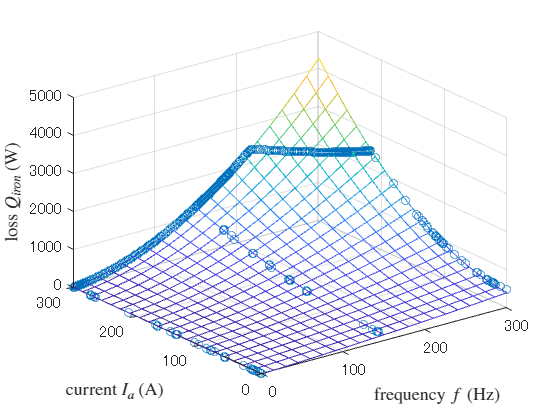

figure("Name","frequency - current - loss");
scatter3(abs(f),abs(Ia),Qiron); hold on;
mesh(f_model,Ia_model,Qiron_model,"FaceAlpha",0);
xlabel("frequency $f$ (Hz)","Interpreter","latex");
ylabel("current $I_a$ (A)","Interpreter","latex");
zlabel("loss $Q_{iron}$ (W)","Interpreter","latex");
ax = gca(); ax.FontSize = 12;